 x1=5;
x2=7;
x3=11;
x4=13;
L=pi;
h=1;

n=5

n = 5

nn=[1:1:n]

nn =      1     2     3     4     5



syms x
syms al
al=sym(pi/2)

$$al = \frac{\pi }{2}$$

syms sn
f= piecewise(abs(x)>al,sym(1),abs(x)<=al,sym(0))

$$f = \left\{ \begin{array}{cl} 1 & \text{ if }\frac{\pi }{2}<\left|x\right|\\ 0 & \text{ if }\left|x\right|\leq \frac{\pi }{2} \end{array}\right.$$

symvar(f)

$$ans = x$$

ezplot(f)

Error using ezplot>ezplot1 (line 460)
The input character vector must be an expression.  Implicit functions of a single variable are not supported.

Error in ezplot (line 158)
                [hp, cax] = ezplot1(cax, f{1}, vars, labels, args{:});

Error in 


%Double A
a0=(1/L)*int(f,-L,L)
a = (1/L)*int(f*cos(pi*sn*x/L),x,-L,L);
aa=subs(a,sn,nn);
aa=double(aa)
%Double B
b = (1/L)*int(f*sin(pi*sn*x/L),x,-L,L);
bb=subs(b,sn,nn);
bb=double(bb)


%Single B
b = (2/L)*int(f*sin(pi*sn*x/L),x,0,L);
bb=subs(b,sn,nn);
bb=double(bb)
aa=zeros(1,n);
a0=0;


%Single A
%syms L
a0=(1/L)*int(f,-L,L)

$$a0 = \frac{5734161139222659\,\pi }{18014398509481984}$$


a = (2/L)*int(f*cos(pi*sn*x/L),x,0,L)

$$a = \frac{5734161139222659\,\left(\sin\left(\pi \,\mathrm{sn}\right)-\sin\left(\frac{\pi \,\mathrm{sn}}{2}\right)\right)}{9007199254740992\,\mathrm{sn}}$$


aa=subs(a,sn,nn)

$$aa = \left(\begin{array}{ccccc} -\frac{5734161139222659}{9007199254740992} & 0 & \frac{1911387046407553}{9007199254740992} & 0 & -\frac{5734161139222659}{45035996273704960} \end{array}\right)$$

aa=double(aa)

aa =    -0.6366         0    0.2122         0   -0.1273


bb=zeros(1,n);

syms al
syms t
%bb=[0.9081,-0.0986,-0.5223,0.0154]
ffou=(a0/2)+sum(aa.*cos(pi.*nn.*x./L)+bb.*sin(pi.*nn.*x./L),0);
al = sym(1)

$$al = 1$$

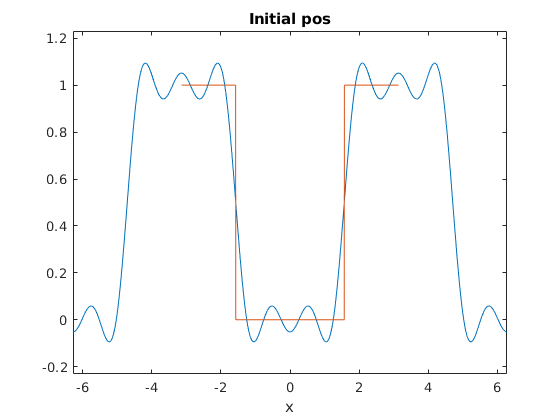

%t = sym(42)
ezplot(ffou)
title("Initial pos"),
hold on
ffou=sum( bb.*cos(al.*pi.*nn.*t./L).*sin(pi.*nn.*x./L));
xx=linspace(-L,L,1000);
fpl=subs(f,x,xx);%f plot
plot(xx,fpl);
hold off

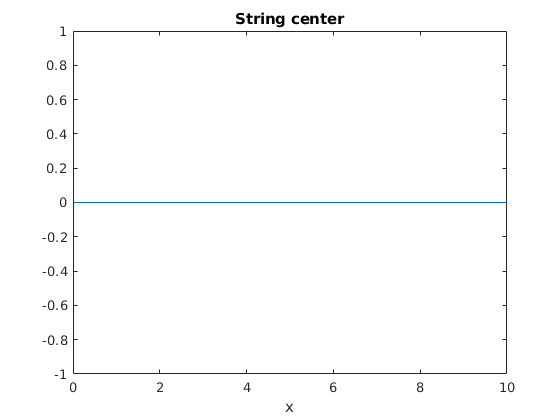




ezplot(subs(ffou,x,L/2),0,10)
title("String center")

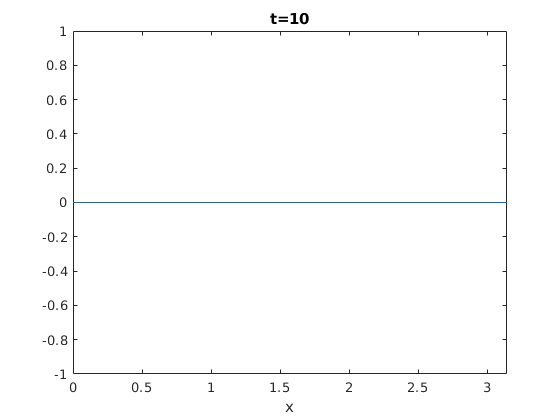


ezplot(subs(ffou,t,10),[0,L])
title("t=10")

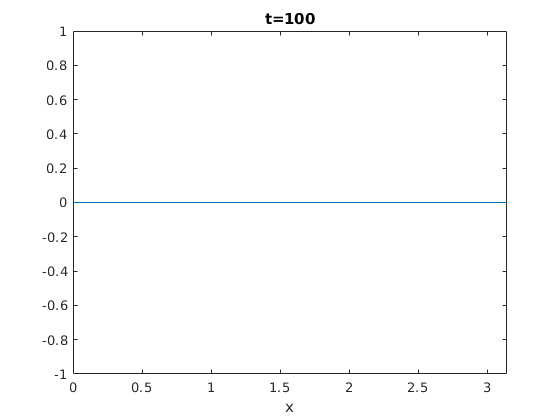

ezplot(subs(ffou,t,100),[0,L])
title("t=100")

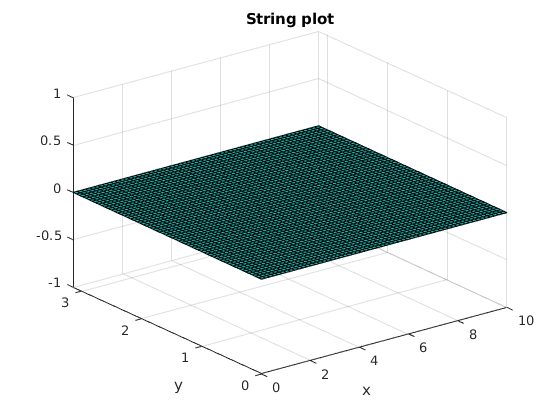


ezsurf(ffou,[0,10,0,L])
title("String plot")

%ezplot(ffou,0,L)
%hold off



%Parseval
p = (1/L)*int((f*f),x,-L,L)
pp=a0/2+sum(aa.^2.+bb.^2)
double(pp)
b = (2/L)*int(f*sin(pi*sn*x/L),x,0,L);
bb=subs(b,sn,nn);
bb=double(bb)
p1 = (2/L)*int((f*f),x,0,L)
pp1=sum(bb.^2)
double(pp1)
%ezplot(xx,yy)